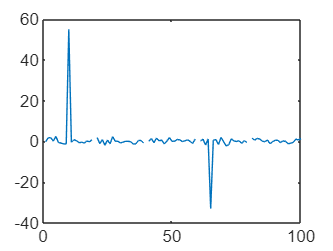

x = 1:100;
date = randn(1,100);
date(20:20:80)=NaN;
date(10) = 55;
date(65) = -33;
data(56) = 44;
plot(date);

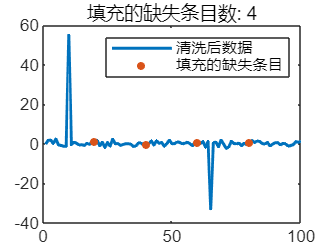

% 填充缺失数据
[cleanedData,missingIndices] = fillmissing(date,"linear");

% 显示结果
figure

% 绘制清洗后的数据
plot(cleanedData,"SeriesIndex",1,"LineWidth",1.5,"DisplayName","清洗后数据")
hold on

% 绘制填充的缺失条目
plot(find(missingIndices),cleanedData(missingIndices),".","MarkerSize",12, ...
    "SeriesIndex",2,"DisplayName","填充的缺失条目")
title("填充的缺失条目数: " + nnz(missingIndices))

hold off
legend

clear missingIndices